## Transducer modelling:

 **Sittig Transfer matrix:**

clear all
x=1

x = 1


% variables
w=linspace(1,8000000,2*10000)   % System frequency in rad/s

w = 	1.0e+06 *

    0.0000    0.0004    0.0008    0.0012    0.0016    0.0020    0.0024    0.0028    0.0032    0.0036    0.0040    0.0044    0.0048    0.0052    0.0056    0.0060    0.0064    0.0068    0.0072    0.0076    0.0080    0.0084    0.0088    0.0092    0.0096    0.0100    0.0104    0.0108    0.0112    0.0116    0.0120    0.0124    0.0128    0.0132    0.0136    0.0140    0.0144    0.0148    0.0152    0.0156    0.0160    0.0164    0.0168    0.0172    0.0176    0.0180    0.0184    0.0188    0.0192    0.0196


a=2.5*10^-3                          % Radius of the piezoelectric plate

a = 0.0025

rho=7.8*10^3                         % Piezoelectric plate density

rho = 7800

c_33=16.6*10^10                      % Elastic constant of the plate

c_33 = 1.6600e+11

d=2*10^-3                            % plate thickness

d = 0.0020

Z_b=x*w;                             % Acoustic impedance of the backing plate (this is a function of frequency)
d_33=265*10^-12                      % Piezoelectric charge coefficient

d_33 = 2.6500e-10

s_33=14.2*10^-12                     % Elastic compliance coefficient

s_33 = 1.4200e-11

epsilon_0=8.854*10^-12               % Vacuum permitivity

epsilon_0 = 8.8540e-12

epsilon_33=1200*epsilon_0            % relative Permativity

epsilon_33 = 1.0625e-08

Beta_33= epsilon_0/epsilon_33        % the dielectric impermeability of the plate at constant strain,

Beta_33 = 8.3333e-04

% equations
h_33= d_33/(s_33*epsilon_33);        % Piezoelectric stiffness constant for the plate
v_o=sqrt(c_33/rho);                  % compressional wave speed from piezoelectric
k=w/v_o                              % wave number for the peizoelectric plate

k = 	1.0e+03 *

    0.0000    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0042


S=pi*a^2                             % Piezoelectric surface area

S = 1.9635e-05

C_o=S/(Beta_33*d)                    % the clamped capacitance of the plate

C_o = 11.7810

n=h_33*C_o                           % A given constant

n = 2.0693e+10

Z_o=rho*v_o*S                        % plane wave acoustic impedance of the piezoelectric plate

Z_o = 706.5310

TAe_matrix = zeros(length(w),1);
TAa_matrix = zeros(length(w),1);
TA_matrix = zeros(length(w),1);


% Matricies
for p=1:length(w)
    
    steps1 = 2*p - 1;
    steps2 = 2*p;
TAe_matrix(steps1:steps2,1:2) =[1/n n/(1i*w(p)*C_o); -1i*w(p)*C_o 0];         %Transducer electrical matrix
TAa_matrix(steps1:steps2,1:2) =(1/(Z_b(p)-1i*Z_o*tan(k(p)*d/2)))*[Z_b(p)+1i*Z_o*cot(k(p)*d) (Z_o)^2+1i*Z_o*Z_b(p)*cot(k(p)*d); 1 Z_b(p)-2*1i*Z_o*tan(k(p)*d/2)];     %Transducer acoustic matrix


TA_matrix(steps1:steps2,1:2) = TAe_matrix(steps1:steps2,1:2)*TAa_matrix(steps1:steps2,1:2); %Sittig model matrix



end



**Acoustic Impedence **$Z_r^{A:a}$

%equations
c=1500                  % compresisonal wave speed in fluid

c = 1500

S_a=S                   % effective face area of the Piezoelectric

S_a = 1.9635e-05

rho_2=900               % Denstiy of the fluid

rho_2 = 900

Z_r=S_a*rho_2*c         % Acoustic radiation impedance - just in case we want to put in the Ka condition later.

Z_r = 26.5072

**Sensitivity **$S_{\textrm{vI}}$**:**

S_vI = zeros(length(w),1);

for kl = 1:length(w)
    
    ste2 = 2*kl;
  S_vI(kl)=1/(Z_r*TA_matrix(ste2,1)+TA_matrix(ste2,2)); %Sensitivity for vI.  
end


**Transducer electrical impedance :**

Z_in = zeros(length(w),1);

for wen = 1:length(w)
ste3 = 2*wen-1;
ste4 = 2*wen;
Z_in(wen) =(Z_r*TA_matrix(ste3,1)+TA_matrix(ste3,2))/(Z_r*TA_matrix(ste4,1)+TA_matrix(ste4,2)); %Electrical impedance of the transducer
end

**Final transfer function **$S_{\textrm{FV}}$**:**

S_FV = zeros(length(w),1)

S_FV =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


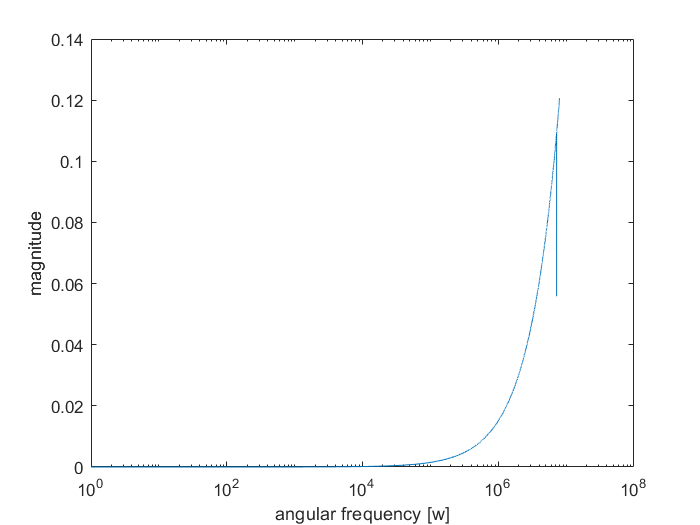


for phi = 1:length(w)
 S_FV(phi) =Z_r*S_vI(phi)/Z_in(phi); %Sensitivity FV  
end


semilogx(w,(abs(S_FV)))
xlabel('angular frequency [w]')
ylabel(['magnitude'])

[h2h2 sd] = max(S_FV(1:300))

h2h2 = -0.0000 + 0.0018i

sd = 300

hauh = w(sd)/(2*pi)

hauh = 1.9036e+04

disp(hauh)

   1.9036e+04




L = length(w);

hai = fft(S_FV);
Fs = w(end)/(2*pi)

Fs = 1.2732e+06


P2 = abs(hai/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
semilogx(f,P1) 
[fd jk]  = max(P1)

fd = 0.0603

jk = 1

freq = w(jk)/(2*pi)

freq = 0.1592

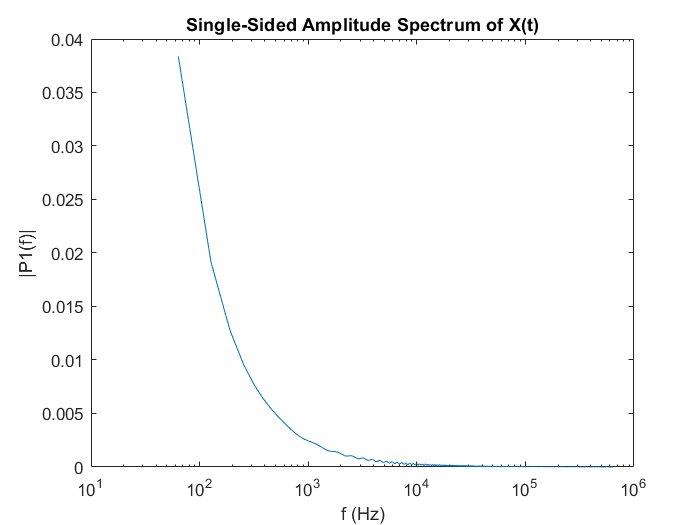


title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

%ylim([-5 5])
%xlim([1 1.000001])

